# Voice Activity Detection Using a Trained Network

We will use a pre-trained Voice Activity Detection (VAD) network to detect the voice activity of a given noisy audio track.

Note: for the following exercise, please turn the speakers on.

This livescript requires the [DSP System Toolbox](https://www.mathworks.com/help/dsp/index.html?s_tid=CRUX_lftnav). 

Some of the functions used in this livescript require the Signal Processing Toolbox™ or the Matlab Audio Toolbox™. If these support packages are not installed, the functions provide the download links.


% Clear workspace and command window
clear;
clc;

## Load pre-trained network and feature extractor object

Load a pretrained network and a configured [audioFeatureExtractor](docid:audio_ref#mw_b56cd7dc-af31-4da4-a43e-b13debc30322) object. The network was trained to detect speech in a low SNR environments given features output from the `audioFeatureExtractor` object.

load('Audio_VoiceActivityDetectionExample.mat','speechDetectNet','afe')

## Create a noisy signal

First we create a noisy signal to detect, injecting noise into a clean speech audio track.

First, we load the clean audio signal

fs = 16e3;  % Sampling frequence
[speech,fileFs] = audioread('Counting-16-44p1-mono-15secs.wav'); % Clean audio signal
speech = resample(speech,fs,fileFs); % Resempling the audio to 16kHz 
speech = speech/max(abs(speech));   %normalize the signal
sound(speech,fs)                    %Listen the audio 

Then we add the noise signal.

[noise,fileFs] = audioread('WashingMachine-16-8-mono-1000secs.mp3'); % Noise
noise = resample(noise,fs,fileFs);

SNR = -20;  %Signal to Noise Ratio
noiseGain = 10^(-SNR/20) * norm(speech) / norm(noise);

noisySpeech = speech + noiseGain*noise(1:numel(speech)); % Create the noisy speech audio
noisySpeech = noisySpeech./max(abs(noisySpeech));

sound(noisySpeech,fs); 

## Extract features from the speech data

Extract features from the speech data and then normalize them. Orient the features so that time is across columns.

features = extract(afe,noisySpeech);
features = (features - mean(features,1)) ./ std(features,[],1);
features = features';

## Detect voice activity using the pre-trained VAD network

Pass the features through the speech detection network to classify each feature vector as belonging to a frame of speech or not.

decisionsCategorical = classify(speechDetectNet,features);

Each decision corresponds to an analysis window analyzed by the `audioFeatureExtractor`. Replicate the decisions so that they are in one-to-one correspondence with the audio samples. Plot the speech, the noisy speech, and the VAD decisions.

decisionsWindow = 1.2*(double(decisionsCategorical)-1);
decisionsSample = [repelem(decisionsWindow(1),numel(afe.Window)), ...
                   repelem(decisionsWindow(2:end),numel(afe.Window)-afe.OverlapLength)];


t = (0:numel(decisionsSample)-1)/afe.SampleRate;
plot(t,noisySpeech(1:numel(t)), ...
     t,speech(1:numel(t)), ...
     t,decisionsSample);
 xlabel('Time (s)')
 ylabel('Amplitude')
 legend('Noisy Speech','Speech','VAD','Location','southwest')

### Use VAD in a streaming environment

You can also use the trained VAD network in a streaming context. To simulate a streaming environment, first save the speech and noise signals as WAV files. To simulate streaming input, you will read frames from the files and mix them at a desired SNR.

audiowrite('Speech.wav',speech,fs)
audiowrite('Noise.wav',noise,fs)

To apply the VAD network to streaming audio, you have to trade off between delay and accuracy. Define parameters for the streaming voice activity detection in noise demonstration. You can set the duration of the test, the sequence length fed into the network, the sequence hop length, and the SNR to test. Generally, increasing the sequence length increases the accuracy but also increases the lag. You can also choose the signal output to your device as the original signal or the noisy signal.

testDuration = 20;

sequenceLength = 400;
sequenceHop = 20;
SNR = -20;
noiseGain = 10^(-SNR/20) * norm(speech) / norm(noise);

signalToListenTo = "noisy";

Call the streaming demo helper function to observe the performance of the VAD network on streaming audio. The parameters you set using the live controls do not interrupt the streaming example. After the streaming demo is complete, you can modify parameters of the demonstration, then run the streaming demo again. You can find the code for the streaming demo in the Supporting Functions.

helperStreamingDemo(speechDetectNet,afe, ...
                    'Speech.wav','Noise.wav', ...
                    testDuration,sequenceLength,sequenceHop,signalToListenTo,noiseGain);

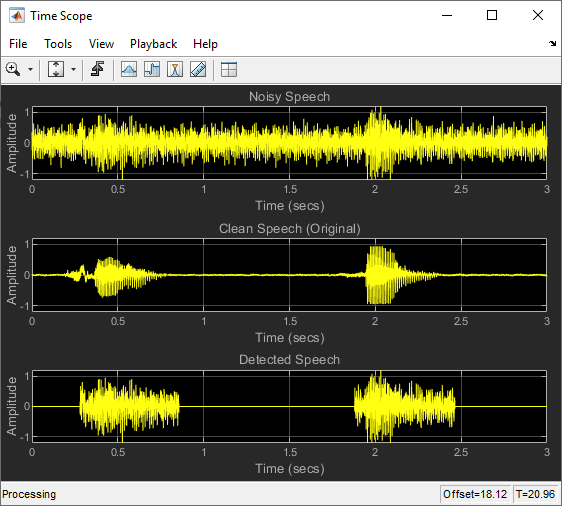

## Further Practice

In a noisy scenario, we can perform the VAD by first denoising the audio signal and then performing a classical VAD. Try to use an audio denoising technique (eg. you can use the [denoiseNetwork](https://it.mathworks.com/help/deeplearning/ug/denoise-speech-using-deep-learning-networks.html) in this example), followed by the [`detectSpeech`](https://it.mathworks.com/help/audio/ref/detectspeech.html) function.

## Further readings

[Audio Processing Using Deep Learning](https://it.mathworks.com/help/deeplearning/audio-processing-using-deep-learning.html)

[Extract Audio Features](https://it.mathworks.com/help/audio/ref/extractaudiofeatures.html) and [audioFeatureExtractor](https://it.mathworks.com/help/audio/ref/audiofeatureextractor.html)

## Helper Functions

### Streaming Demo

function helperStreamingDemo(speechDetectNet,afe,cleanSpeech,noise,testDuration,sequenceLength,sequenceHop,signalToListenTo,noiseGain)

Create [dsp.AudioFileReader](https://www.mathworks.com/help/dsp/ref/dsp.audiofilereader-system-object.html) objects to read from the speech and noise files frame by frame.

    speechReader = dsp.AudioFileReader(cleanSpeech,'PlayCount',inf);
    noiseReader = dsp.AudioFileReader(noise,'PlayCount',inf);
    fs = speechReader.SampleRate;

Create a [dsp.MovingStandardDeviation](https://www.mathworks.com/help/dsp/ref/dsp.movingstandarddeviation-system-object.html) object and a [dsp.MovingAverage](https://www.mathworks.com/help/dsp/ref/dsp.movingaverage-system-object.html) object. You will use these to determine the standard deviation and mean of the audio features for normalization. The statistics should improve over time.

    movSTD = dsp.MovingStandardDeviation('Method','Exponential weighting','ForgettingFactor',1);
    movMean = dsp.MovingAverage('Method','Exponential weighting','ForgettingFactor',1);

Create three [dsp.AsyncBuffer](docid:dsp_ref#bvkqgmw-1) objects. One to buffer the input audio, one to buffer the extracted features, and one to buffer the output buffer. The output buffer is only necessary for visualizing the decisions in real time.

    audioInBuffer = dsp.AsyncBuffer;
    featureBuffer = dsp.AsyncBuffer;
    audioOutBuffer = dsp.AsyncBuffer;

For the audio buffers, you will buffer both the original clean speech signal, and the noisy signal. You will play back only the specified `signalToListenTo`. Convert the `signalToListenTo` variable to the channel you want to listen to.

    channelToListenTo = 1;
    if strcmp(signalToListenTo,"clean")
        channelToListenTo = 2;
    end

Create a [dsp.TimeScope](docid:dsp_ref#bsnirq1-1) to visualize the original speech signal, the noisy signal that the network is applied to, and the decision output from the network.

    scope = timescope('SampleRate',fs, ...
        'BufferLength',fs*3*3, ...
        'YLimits',[-1.2 1.2], ...
        'TimeSpanOverrunAction','Scroll', ...
        'ShowGrid',true, ...
        'NumInputPorts',3, ...
        'LayoutDimensions',[3,1], ...
        'Title','Noisy Speech');
    scope.ActiveDisplay = 2;
    scope.Title = 'Clean Speech (Original)';
    scope.ActiveDisplay = 3;
    scope.Title = 'Detected Speech';

Create an [audioDeviceWriter](docid:audio_ref#bu5y2a_-1) object to play either the original or noisy audio from your speakers.

    deviceWriter = audioDeviceWriter('SampleRate',fs);

Initialize variables used in the loop.

    windowLength = numel(afe.Window);
    hopLength = windowLength - afe.OverlapLength;
    myMax = 0;
    audioBufferInitialized = false;
    featureBufferInitialized = false;

Run the streaming demonstration.

    tic
    while toc < testDuration
    
        % Read a frame of the speech signal and a frame of the noise signal
        speechIn = speechReader();
        noiseIn = noiseReader();
        
        % Mix the speech and noise at the specified SNR
        noisyAudio = speechIn + noiseGain*noiseIn;
        
        % Update a running max for normalization
        myMax = max(myMax,max(abs(noisyAudio)));
        
        % Write the noisy audio and speech to buffers
        write(audioInBuffer,[noisyAudio,speechIn]);
        
        % If enough samples are buffered,
        % mark the audio buffer as initialized and push the read pointer
        % for the audio buffer up a window length.
        if audioInBuffer.NumUnreadSamples >= windowLength && ~audioBufferInitialized
            audioBufferInitialized = true;
            read(audioInBuffer,windowLength);
        end
        
        % If enough samples are in the audio buffer to calculate a feature
        % vector, read the samples, normalize them, extract the feature vectors, and write
        % the latest feature vector to the features buffer.
        while (audioInBuffer.NumUnreadSamples >= hopLength) && audioBufferInitialized
            x = read(audioInBuffer,windowLength + hopLength,windowLength);
            write(audioOutBuffer,x(end-hopLength+1:end,:));
            noisyAudio = x(:,1);
            noisyAudio = noisyAudio/myMax;
            features = extract(afe,noisyAudio);
            write(featureBuffer,features(2,:));
        end
        
        % If enough feature vectors are buffered, mark the feature buffer
        % as initialized and push the read pointer for the feature buffer
        % and the audio output buffer (so that they are in sync).
        if featureBuffer.NumUnreadSamples >= (sequenceLength + sequenceHop) && ~featureBufferInitialized
            featureBufferInitialized = true;
            read(featureBuffer,sequenceLength - sequenceHop);
            read(audioOutBuffer,(sequenceLength - sequenceHop)*windowLength);
        end
        
       while featureBuffer.NumUnreadSamples >= sequenceHop && featureBufferInitialized
            features = read(featureBuffer,sequenceLength,sequenceLength - sequenceHop);
            features(isnan(features)) = 0;
            
            % Use only the new features to update the
            % standard deviation and mean. Normalize the features.
            localSTD = movSTD(features(end-sequenceHop+1:end,:));
            localMean = movMean(features(end-sequenceHop+1:end,:));
            features = (features - localMean(end,:)) ./ localSTD(end,:);
            
            decision = classify(speechDetectNet,features');
            decision = decision(end-sequenceHop+1:end);
            decision = double(decision)' - 1;
            decision = repelem(decision,hopLength);
            
            audioHop = read(audioOutBuffer,sequenceHop*hopLength);
            
            % Listen to the speech or speech+noise
            deviceWriter(audioHop(:,channelToListenTo));
            
            % Visualize the speech+noise, the original speech, and the
            % voice activity detection.
            scope(audioHop(:,1),audioHop(:,2),audioHop(:,1).*decision)
       end
    end
    release(deviceWriter)
    release(audioInBuffer)
    release(audioOutBuffer)
    release(featureBuffer)
    release(movSTD)
    release(movMean)
    release(scope)
end